# **Visualize the spatial distributions of datasets in the NCEI Paleo Data Search archive**

**1. Select a data type**

ids = get_dataTypeId();
datatypes = fieldnames(ids);
datatype = datatypes(1);
JSON = search_paleo(ids.(datatype{1}));

**2. Adjust latitude and longitude ranges**

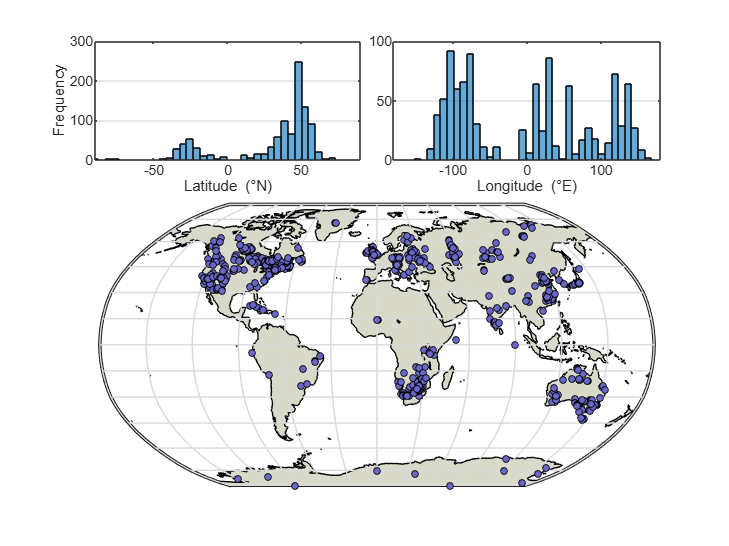

latitude_range =[-90 90];
longitude_range = [-180 180];
map_projection = "Robinson";

% Initialize vectors vectors
lats = [];
lons = []; 
studyIDs = [];

% Loop through sites
num_studies = length(JSON.study);  % Count number of studies returned
study_list = JSON.study;  % Extract list of studies returned
for i = 1:num_studies  % Loop through studies
    num_sites = length(study_list(i).site);  % Count number of sites in the study
    for j = 1:num_sites  % Loop through sites within the study
        % Extract latitude, convert to double, and append to vector
        if isempty(study_list(i).site(j).geo)
            continue
        end
        lat = study_list(i).site(j).geo.geometry.coordinates(1);
        lon = study_list(i).site(j).geo.geometry.coordinates(2);
        lats = [lats; str2double(lat{1})];
        lons = [lons; str2double(lon{1})];
        sid = study_list.NOAAStudyId;
        studyIDs = [studyIDs; string(sid)];
    end
end

% Create visualization
close all
figure()
t=tiledlayout('TileSpacing','compact');

%
% HISTOGRAMS
%
nexttile([2 4])
 h1=histogram(lats,'NumBins',36); set(gca,'YGrid','on')
 xlim(latitude_range)
 xlabel('Latitude (\circN)')
 ylabel('Frequency')
nexttile([2 4])
 h2=histogram(lons,'NumBins',36); set(gca,'YGrid','on')
 xlim(longitude_range)
 xlabel('Longitude (\circE)')

%
% MAP VISUALIZATION
%
nexttile([4 8])
warning off
h=axesm('MapProjection',lower(map_projection{1}),...
    'MapLatLimit',latitude_range,...
    'MapLonLimit',longitude_range);
warning on
    load coastlines
    fillm(coastlat,coastlon,'FaceColor',[0.85 0.85 0.79])
    tightmap
    gridm
    hold on
     S=scatterm(lats,lons);
     S.Children.MarkerFaceColor=[104 104 202]./255;
     S.Children.MarkerEdgeColor='k';
     S.Children.SizeData=15;
    hold off
    set(gca,'XColor','none','YColor','none','GridLineStyle','-')
    gridlines=findobj(gcf,'Type','line');
    [gridlines.LineStyle] = deal('-');
    [gridlines.Color] = deal([0.85 0.85 0.85]);
    framem

    %{
       % Alternative mapping commands
       gs = geoscatter(lats,lons,20,[0 0.4470 0.7410],'o','filled','MarkerEdgeColor','k');
       geolimits(latitude_range, longitude_range);
    %}